Call the ROC script

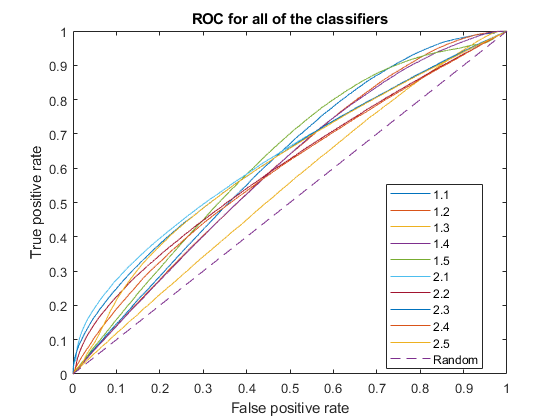

AUC11 = 0.6160

AUC12 = 0.5988

AUC13 = 0.5439

AUC14 = 0.5960

AUC15 = 0.6261

AUC21 = 0.6320

AUC22 = 0.6011

AUC23 = 0.6256

AUC24 = 0.5907

AUC25 = 0.6165

roc_v8_second_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9609

ans = 165

ans = 0.9960

ans = 0.0042

ans = 0.9960

ans = 0.7932

ans = 0.9365

Classifier 2

ans = 0.9749

ans = 170

ans = 0.9878

ans = 0.0133

ans = 0.9878

ans = 0.8425

ans = 0.9507

Classifier 3

ans = 0.9554

ans = 185

ans = 0.9163

ans = 0.1198

ans = 0.9163

ans = 0.9777

ans = 0.9981

Classifier 4

ans = 0.9857

ans = 158

ans = 0.9784

ans = 0.0234

ans = 0.9784

ans = 0.7723

ans = 0.8951

Classifier 5

ans = 0.9860

ans = 146

ans = 0.9965

ans = 0.0038

ans = 0.9965

ans = 0.6691

ans = 0.8559

Classifier 6

ans = 0.0307

ans = 35

ans = 0.9959

ans = 0.0036

ans = 0.9959

ans = 0.0945

ans = 0.2673

Classifier 7

ans = 0.0014

ans = 38

ans = 0.9773

ans = 0.0228

ans = 0.9773

ans = 0.1294

ans = 0.2650

Classifier 8

ans = 8.8480e-04

ans = 43

ans = 0.9904

ans = 0.0092

ans = 0.9904

ans = 0.1397

ans = 0.3052

Classifier 9

ans = 0.0012

ans = 56

ans = 0.9564

ans = 0.0425

ans = 0.9564

ans = 0.2254

ans = 0.3576

Classifier 10

ans = 3.0247e-06

ans = 61

ans = 0.9888

ans = 0.0116

ans = 0.9888

ans = 0.2268

ans = 0.4071

Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val = 0.9965

ind = 5

Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom = 0.6945

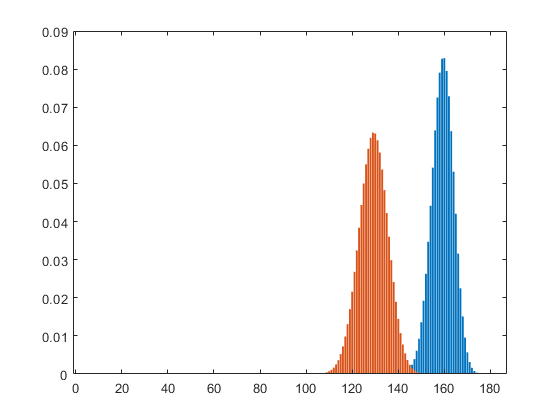

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors = 1.8486

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end
cost = cost * 521

cost = 135981

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 17.0530

Save results

save('./results_characterization/v8_second_op_1.mat','selectedPoints');